# **Digital Communications Lab**

## **Prelab 2**

### ** Soroush Mesforush Mashhad - 810198472**

**Question 1**

Here we shall write a function that performs convolution, then we shall test the results.

%The function is included in the conv_m.mlx file.
%Now we go on to test it.
x = [3, 11, 7, 0, -1, 4, 2];
h = [2, 3, 0, -5, 2, 1];
%Testing with built in function of MATLAB.
yMATLAB=conv(x,h);
disp("The convoltion with the built in MATLAB function is : ");

The convoltion with the built in MATLAB function is : 


disp(yMATLAB)

     6    31    47     6   -51    -5    41    18   -22    -3     8     2



%Testing with our function
yME=conv_m(x,h);
disp("The convoltion with my function is : ");

The convoltion with my function is : 


disp(yME)

     6    31    47     6   -51    -5    41    18   -22    -3     8     2



**Question 2**

**Part A**

x_n=[1,2,3,4,5];
h_n=[6,7,8,9];
y=conv_m(x_n,h_n);
disp('The convolution using conv_m.m is as follows:')

The convolution using conv_m.m is as follows:


disp(y)

     6    19    40    70   100    94    76    45



**Part B**

The code below and the theory behind it has been explained fully in the PDF file included.

xCol=[1;2;3;4;5;];
hCol=[6;7;8;9];
yCol=zeros([8 5]);
H=[hCol(1) 0 0 0 0 ;
   hCol(2) hCol(1) 0 0 0;
   hCol(3) hCol(2) hCol(1) 0 0;
   hCol(4) hCol(3) hCol(2) hCol(1) 0;
   0 hCol(4) hCol(3) hCol(2) hCol(1);
   0    0    hCol(4) hCol(3) hCol(2);
   0    0       0    hCol(4) hCol(3);
   0    0       0       0    hCol(4)]

H =      6     0     0     0     0
     7     6     0     0     0
     8     7     6     0     0
     9     8     7     6     0
     0     9     8     7     6
     0     0     9     8     7
     0     0     0     9     8
     0     0     0     0     9


yCol=H*xCol;
disp('The convolution result using the matrix form is :')

The convolution result using the matrix form is :


disp(yCol')

     6    19    40    70   100    94    76    45



**Part C(ت)**

This part has been fully explained in the PDF file.

**Part D(ث)**

The convolution function has been written in the conv_tp.m file

x = [3, 11, 7, 0, -1, 4, 2];
h = [2, 3, 0, -5, 2, 1];
%Testing with utilizing toeplitz function
yToep=conv_tp(x,h,1);
disp("The convoltion with utilizing toeplitz function is : ");

The convoltion with utilizing toeplitz function is : 


disp(yToep)

     6    31    47     6   -51    -5    41    18   -22    -3     8     2



%Testing without utilizing toeplitz function
yNoToep=conv_tp(x,h,0);
disp("The convoltion without utilizing toeplitz function is : ");

The convoltion without utilizing toeplitz function is : 


disp(yNoToep)

     6    31    47     6   -51    -5    41    18   -22    -3     8     2



**Question 3**

Here we shall study the concept of the Discrete Fourier Transform.

PointsN = 256^2

PointsN = 65536

N = 16

N = 16

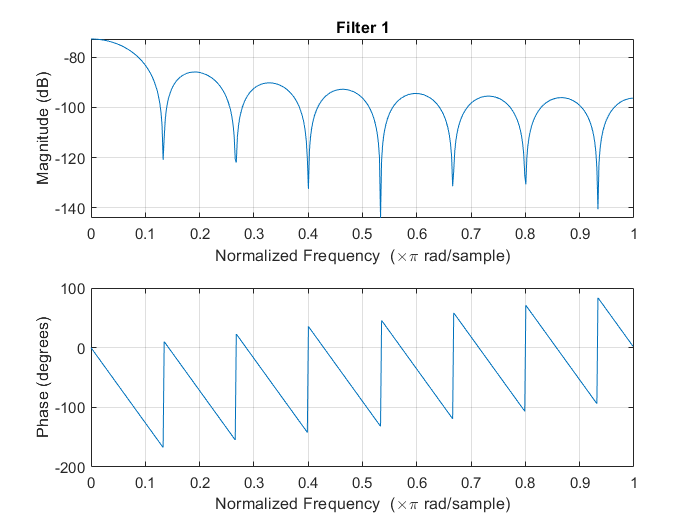

%We need to create the WN matrix, to do so we use the ones matrix 
WN = ones(N-1);
 %In the following loops we create WN matrix Accordingly.
 for i = 1 : N-1
      for j = 1 : N-1
          WN(i+1,j+1) = exp(-1j*2*pi/N)^(i*j);
      end
 end
 %Now we need to cut the needed rows for the FIR filters.
 FIR1Coef=WN(1,:);
 FIR2Coef=WN(2,:);
 FIR3Coef=WN(10,:);
 freqz(FIR1Coef,PointsN)
 title('Filter 1')

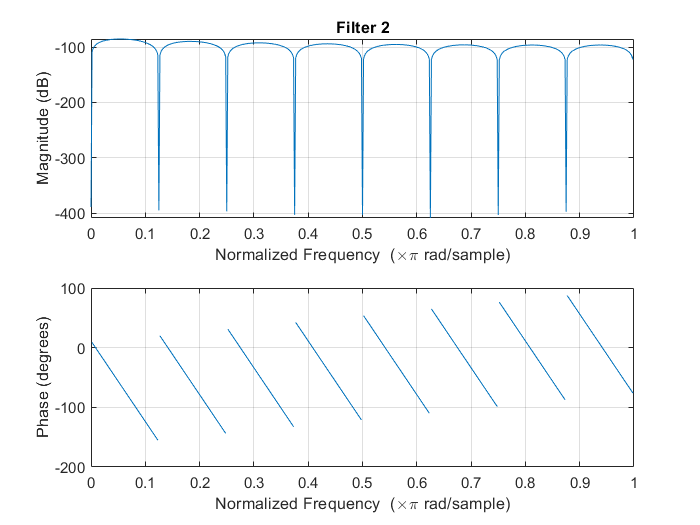

 freqz(FIR2Coef,PointsN)
 title('Filter 2')

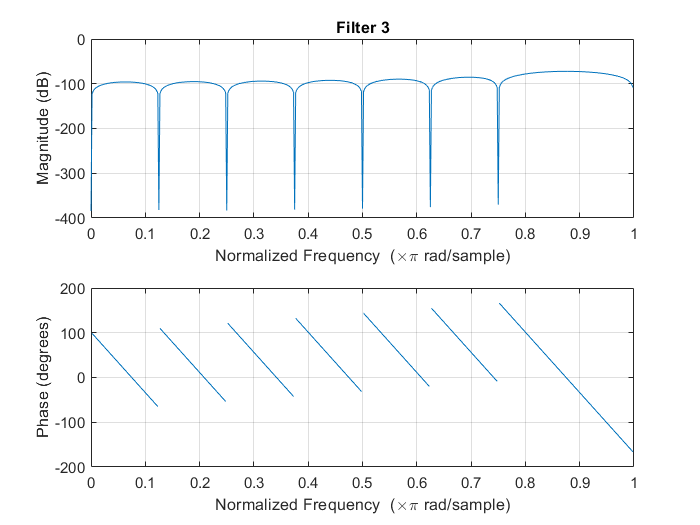

 freqz(FIR3Coef,PointsN)
 title('Filter 3')

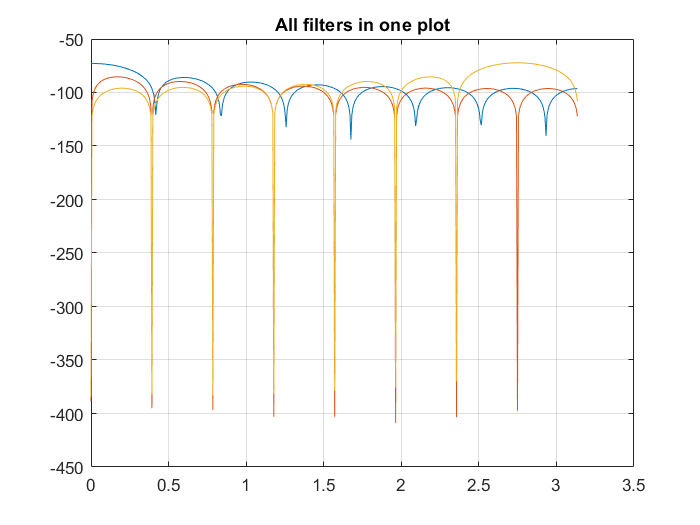

 %Now we go on to plot the filters in one plot, to do so we must take the
 %outputs of the freqz function
 [hFil1,wFil1] = freqz(FIR1Coef,PointsN);
 [hFil2,wFil2] = freqz(FIR2Coef,PointsN);
 [hFil3,wFil3] = freqz(FIR3Coef,PointsN);
 %Here we plot them in the logarithmic scale in one plot
  plot(wFil1,20*log10(abs(hFil1)))
  hold on
  plot(wFil2,20*log10(abs(hFil2)))
  plot(wFil3,20*log10(abs(hFil3)))
  title('All filters in one plot')
  grid on

**Question 4**

This part has been completed in the PDF file.